W - весовой коеф

W = -6

W = -6

P - коеф смещения

p = 4

p = 4

x = 0 : 10

x =      0     1     2     3     4     5     6     7     8     9    10


y = W .* x + p

y =      4    -2    -8   -14   -20   -26   -32   -38   -44   -50   -56


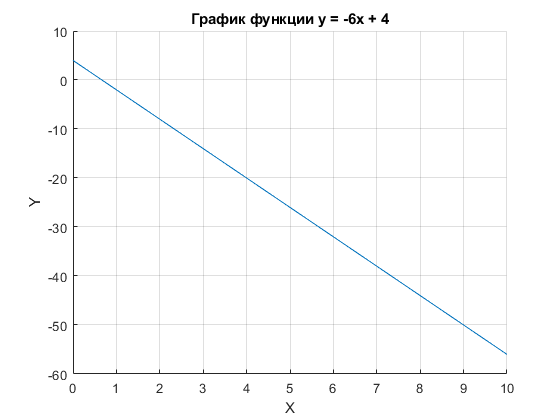

plot(x,y),grid on,box off , title('График функции y = -6x + 4'),xlabel("X"),ylabel("Y");

points_X_Black = [1 2 3 4 5 6 7 8 9 10]

points_X_Black =      1     2     3     4     5     6     7     8     9    10


points_X_White = [1 2 3 4 5 6 7 8 9 10]

points_X_White =      1     2     3     4     5     6     7     8     9    10


point_Y_Black = [-5 -10  -17  -22  -29 -36 -40 -46 -54 -59]

point_Y_Black =     -5   -10   -17   -22   -29   -36   -40   -46   -54   -59


point_Y_White = [5 7 0 -2 -4 -5 -7 -15 -25 -10]

point_Y_White =      5     7     0    -2    -4    -5    -7   -15   -25   -10


P = [points_X_Black points_X_White; point_Y_Black point_Y_White]

P =      1     2     3     4     5     6     7     8     9    10     1     2     3     4     5     6     7     8     9    10
    -5   -10   -17   -22   -29   -36   -40   -46   -54   -59     5     7     0    -2    -4    -5    -7   -15   -25   -10


T = [0 0 0 0 0 0 0 0 0 0 ...
	1 1 1 1 1 1 1 1 1 1]

T =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


p_14 = newp(minmax(P),1)

p_14 =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect:

p_14 = train(p_14,P,T)

p_14 =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect:

sim(p_14,P)

ans =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


plotpv(P,T);
hold on
plotpc(p_14.IW{1,1},p_14.b{1});
hold on
y = W *P(1, :) + p

y =     -2    -8   -14   -20   -26   -32   -38   -44   -50   -56    -2    -8   -14   -20   -26   -32   -38   -44   -50   -56


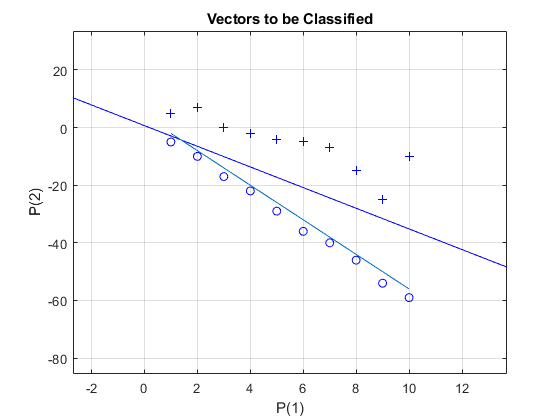

plot(P(1,:),y),grid;